clear all;

% Inclusion criteria
min_stroke_age = 0; % Any onset age
min_test_age = 0; % Any test age
min_test_interval = 0.5; % at least 6 months post-onset interval to test

% Get VIPS dataset
project_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_mapping';
beh_csv = readtable(fullfile(project_dir, 'behavior', 'vips_combined_31226.csv'), 'Format', 'auto');
beh_csv = beh_csv(beh_csv.stroke_age >= min_stroke_age,:);
beh_csv = beh_csv(beh_csv.test_age >= min_test_age,:);
beh_csv = beh_csv(beh_csv.yrs2test >= min_test_interval, :);
beh_csv = beh_csv(beh_csv.has_lesion == 1,:);

% Make box plots of stroke onset age at each level of impairment
clf;
tiledlayout(2,3);
domains = {'Left', 'Right', 'Verbal', 'LanguageReception','Cognitive_Behavioral'};
my_names = {'Left SM', 'Right SM', 'Exp. Lang', 'Rec. Lang', 'Cog/Beh'}

my_names = 1×5 cell array
    {'Left SM'}    {'Right SM'}    {'Exp. Lang'}    {'Rec. Lang'}    {'Cog/Beh'}


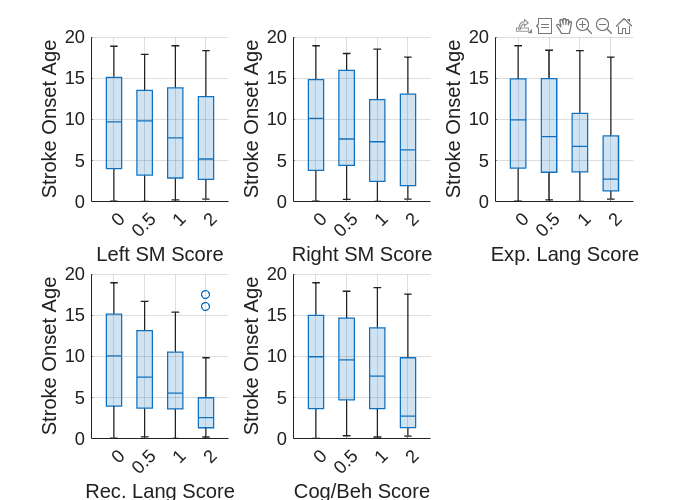

for i = 1:length(my_names)
    nexttile;
    boxchart(categorical(beh_csv.(domains{i})), beh_csv.stroke_age);
    grid on; ylabel('Stroke Onset Age');
    xlabel([my_names{i} ' Score']);
    set(gca, 'FontSize', 14);
end
set(gcf, 'position', [0, 0, 700, 500]);

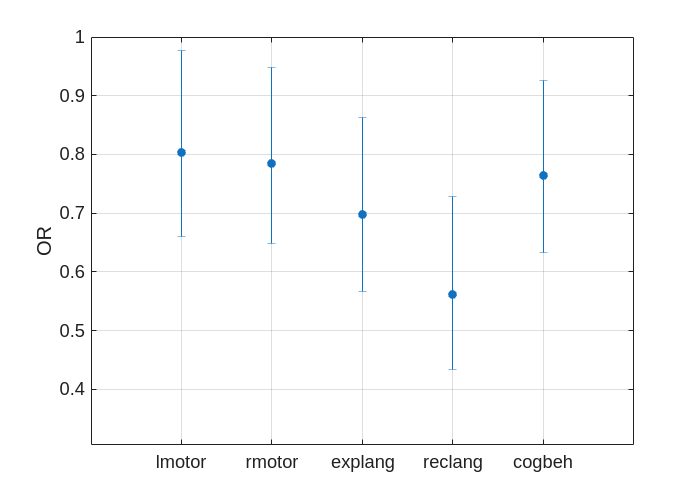

% Fit single variable (age) and multivariable models for each domain and do model comparisons with BIC

% Standardize predictors
beh_csv.stroke_age = zscore(beh_csv.stroke_age);
beh_csv.yrs2test = zscore(beh_csv.yrs2test);
beh_csv.lh_vol = zscore(beh_csv.lh_vol);
beh_csv.rh_vol = zscore(beh_csv.rh_vol);

% Add paths and set variables
addpath('/Shared/boeslab/Users/jcgriffis/vips_psom_mapping/archive_scripts/functions');
domains = {'Left', 'Right', 'Verbal', 'LanguageReception','Cognitive_Behavioral'};
names = {'lmotor', 'rmotor', 'explang', 'reclang', 'cogbeh'};
coeff_age = zeros(length(domains), 1);
age_ci = zeros(length(domains), 2);
nboot = 1000;
bootcoeff = zeros(nboot, length(domains));
Options=statset(UseParallel=true);
for i = 1:length(domains)

    % Recode outcome so that reference group is unimpaired
    Y = zeros(length(beh_csv.(domains{i})),1);
    Y(beh_csv.(domains{i}) == 2) = 0;
    Y(beh_csv.(domains{i}) == 1) = 1;
    Y(beh_csv.(domains{i}) == 0.5) = 2;
    Y(beh_csv.(domains{i}) == 0) = 3;    
    beh_csv.(names{i}) = Y;
    N = length(Y);

    % Age only
    mdl_age.(names{i}) = fitmnr(beh_csv, [names{i} ' ~ stroke_age'], 'ModelType', 'ordinal');
    coeff_age(i,1) = exp(mdl_age.(names{i}).Coefficients.Value(4));
    coeff_ci = coefCI(mdl_age.(names{i}));
    age_ci(i,:) = exp(coeff_ci(4,:));

    % Bootstrap BIC model selection
    fitboot = @(idx) fit_mnr_models(beh_csv(idx,:), domains{i});
    bootcoeff(:,i) = bootstrp(nboot, fitboot, (1:N)', 'Options', Options);

    % Fit candidate models
    mdl4.(names{i}) = fitmnr(beh_csv, [names{i} ' ~ stroke_age + yrs2test + lh_vol + rh_vol + lh_vol*stroke_age + rh_vol*stroke_age'], 'ModelType','ordinal');
    mdl3.(names{i}) = fitmnr(beh_csv, [names{i} ' ~ stroke_age + yrs2test + lh_vol + rh_vol + lh_vol*stroke_age'], 'ModelType','ordinal');    
    mdl2.(names{i}) = fitmnr(beh_csv, [names{i} ' ~ stroke_age + yrs2test + lh_vol + rh_vol + rh_vol*stroke_age'], 'ModelType','ordinal');    
    mdl1.(names{i}) = fitmnr(beh_csv, [names{i} ' ~ stroke_age + yrs2test + lh_vol + rh_vol'], 'ModelType','ordinal');    
    mdl_arr = {mdl1.(names{i}), mdl2.(names{i}), mdl3.(names{i}), mdl4.(names{i})};

    % Get best model across bootstraps
    mdl.(names{i}) = mdl_arr{mode(bootcoeff(:,i))};

end

% Plot cumulative ORs and 95% CIs for age
clf;
errorbar(1:1:length(names), coeff_age, coeff_age-age_ci(:,1), age_ci(:,2)-coeff_age, 'LineStyle', 'None', 'Marker', '.', 'MarkerSize', 20);
set(gca, 'Xtick', 1:1:5); set(gca, 'XtickLabel', names); axis([0, 6, 0.3, 1]); grid on; set(gca, 'FontSize', 14);
ylabel('OR');

% Plot BIC results
clf;
tiledlayout(2,3);
my_names = {'Left SM', 'Right SM', 'Exp. Lang', 'Rec. Lang', 'Cog/Beh'}

my_names = 1×5 cell array
    {'Left SM'}    {'Right SM'}    {'Exp. Lang'}    {'Rec. Lang'}    {'Cog/Beh'}


bootcounts = summary(categorical(bootcoeff))

bootcounts = struct with fields:
          Size: [1000 5]
          Type: 'categorical'
    Categories: {4×1 cell}
        Counts: [4×5 double]
    NumMissing: [0 0 0 0 0]


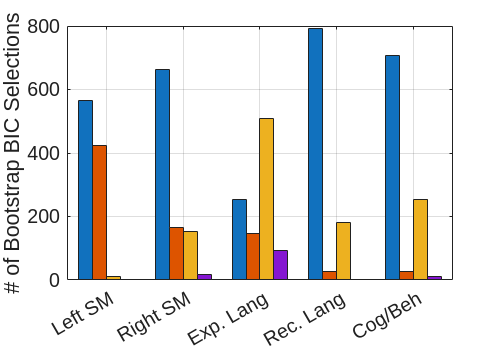

bar(bootcounts.Counts', 'grouped', 'BarWidth', 1);grid on;
ylabel('# of Bootstrap BIC Selections'); set(gca, 'FontSize', 15);
set(gcf, 'position', [0, 0, 500, 350]);set(gca, 'XtickLabel', my_names);

% Plot models

for i = 1:length(names)
    
    % Show model table
    disp(names{i});
    mdl.(names{i});

    % Get coeffs and 95% CIs
    coeffs = exp(mdl.(names{i}).Coefficients.Value(4:end));
    coeff_ci = coefCI(mdl.(names{i})); 
    coeff_ci = coeff_ci(4:end,:); coeff_ci = exp(coeff_ci);
    xnames = replace(mdl.(names{i}).CoefficientNames(4:end), '_', ' ');
    xnames = replace(xnames, 'yrs2test', 'years to test');
    xnames = replace(xnames, ':', ' X ');
    xnames = upper(xnames);

    my_t.(names{i}) = table();
    my_t.(names{i}).Predictors = xnames;
    my_t.(names{i}).coeffs = mdl.(names{i}).Coefficients.Value(4:end);
    my_t.(names{i}).aOR = exp(my_t.(names{i}).coeffs);
    my_t.(names{i}).CIl = coeff_ci(:,1);
    my_t.(names{i}).CIu = coeff_ci(:,2);
    my_t.(names{i}).tstat = mdl.(names{i}).Coefficients.tStat(4:end);
    my_t.(names{i}).pval = mdl.(names{i}).Coefficients.pValue(4:end);
    disp(my_t.(names{i}));
    
end

lmotor


      Predictors        coeffs        aOR        CIl       CIu       tstat        pval   
    _______________    _________    _______    _______    ______    ________    _________

    "STROKE AGE"       -0.087654    0.91608    0.74225    1.1306    -0.81716      0.41384
    "YEARS TO TEST"      0.15495     1.1676    0.95862    1.4221      1.5413      0.12325
    "LH VOL"            -0.47971    0.61896     0.4391    0.8725      -2.741    0.0061252
    "RH VOL"             0.75281      2.123     1.7028    2.6467      6.6968     2.13e-11



rmotor


      Predictors        coeffs       aOR        CIl       CIu       tstat        pval   
    _______________    ________    _______    _______    ______    _______    __________

    "STROKE AGE"        -0.1949    0.82292    0.67154    1.0084    -1.8807      0.060013
    "YEARS TO TEST"    0.019075     1.0193    0.83678    1.2415    0.18968       0.84956
    "LH VOL"            0.83879     2.3136     1.8895    2.8328     8.1263    4.4259e-16
    "RH VOL"           -0.14716    0.86316    0.69707    1.0688    -1.3507       0.17679



explang


         Predictors          coeffs       aOR        CIl        CIu       tstat        pval   
    _____________________    _______    _______    _______    _______    _______    __________

    "STROKE AGE"              -0.285    0.75201    0.59657    0.94796    -2.4144      0.015761
    "YEARS TO TEST"          0.15781     1.1709    0.95063     1.4423     1.4852       0.13749
    "LH VOL"                 0.69673     2.0072     1.6453     2.4487     6.8737    6.2541e-12
    "RH VOL"                  0.3427     1.4087     1.1709     1.6949     3.6358    0.00027715
    "STROKE AGE X LH VOL"    0.27563     1.3174     1.0845     1.6003     2.7792     0.0054496



reclang


      Predictors        coeffs       aOR        CIl        CIu       tstat        pval   
    _______________    ________    _______    _______    _______    _______    __________

    "STROKE AGE"       -0.49164    0.61162    0.46555    0.80353     -3.534    0.00040936
    "YEARS TO TEST"    0.069911     1.0724    0.84286     1.3645    0.56938        0.5691
    "LH VOL"            0.51378     1.6716     1.3823     2.0214     5.3046     1.129e-07
    "RH VOL"            0.24107     1.2726     1.0489      1.544     2.4466      0.014419



cogbeh


      Predictors        coeffs       aOR        CIl       CIu       tstat        pval   
    _______________    ________    _______    _______    ______    _______    __________

    "STROKE AGE"       -0.14638    0.86383    0.70852    1.0532    -1.4488       0.14739
    "YEARS TO TEST"     0.20528     1.2279     1.0195    1.4788     2.1655       0.03035
    "LH VOL"            0.32754     1.3875     1.1668    1.6501     3.7077    0.00020913
    "RH VOL"            0.30086      1.351     1.1321    1.6122     3.3387    0.00084159



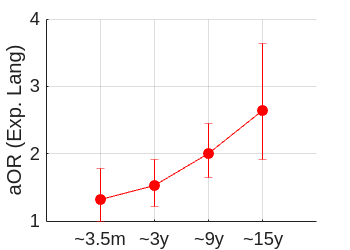

Z = -1.50: Slope = 0.2833, SE = 0.1511, p = 0.0608
Z = -1.00: Slope = 0.4211, SE = 0.1171, p = 0.0003
Z = 0.00: Slope = 0.6967, SE = 0.1014, p = 0.0000
Z = 1.00: Slope = 0.9724, SE = 0.1628, p = 0.0000


% Conditional effects for Expressive Language
addpath('/Shared/boeslab/Users/jcgriffis/vips_psom_mapping/archive_scripts');

% Z-values and labels for age levels
z_vals = [-1.5,-1, 0, 1];
xlabels = {'~3.5m', '~3y', '~9y', '~15y'};

% Expressive lang
clf;
run_cfx_analysis(mdl3.explang, 6, 8, z_vals, xlabels, 'r'); set(gca, 'FontSize',14);set(gcf, 'position', [0, 0, 350, 250]); ylabel('aOR (Exp. Lang)');

% Explore model 4 for exp lang
clf;
run_cfx_analysis(mdl4.explang, 6, 8, z_vals, xlabels, 'r');

Z = -1.50: Slope = 0.2914, SE = 0.1531, p = 0.0571
Z = -1.00: Slope = 0.4222, SE = 0.1187, p = 0.0004
Z = 0.00: Slope = 0.6840, SE = 0.1017, p = 0.0000
Z = 1.00: Slope = 0.9458, SE = 0.1630, p = 0.0000


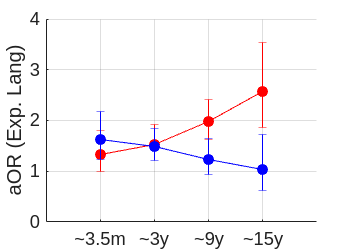

Z = -1.50: Slope = 0.4907, SE = 0.1444, p = 0.0007
Z = -1.00: Slope = 0.3986, SE = 0.1077, p = 0.0002
Z = 0.00: Slope = 0.2144, SE = 0.1476, p = 0.1465
Z = 1.00: Slope = 0.0301, SE = 0.2651, p = 0.9095


hold on; 
run_cfx_analysis(mdl4.explang, 7, 9, z_vals, xlabels, 'b'); set(gca, 'FontSize',14);set(gcf, 'position', [0, 0, 350, 250]); ylabel('aOR (Exp. Lang)');

% Post-hoc analyses of Receptive Language

% Z-values and labels for age levels
z_vals = [-1.5,-1, 0, 1];
xlabels = {'~3.5m', '~3y', '~9y', '~15y'};

% Receptive lang
clf;
run_cfx_analysis(mdl4.reclang, 6, 8, z_vals, xlabels, 'r'); 

Z = -1.50: Slope = 0.3069, SE = 0.1544, p = 0.0469
Z = -1.00: Slope = 0.3883, SE = 0.1191, p = 0.0011
Z = 0.00: Slope = 0.5511, SE = 0.1016, p = 0.0000
Z = 1.00: Slope = 0.7139, SE = 0.1646, p = 0.0000


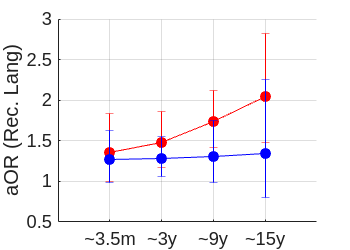

Z = -1.50: Slope = 0.2359, SE = 0.1294, p = 0.0683
Z = -1.00: Slope = 0.2479, SE = 0.0989, p = 0.0122
Z = 0.00: Slope = 0.2718, SE = 0.1482, p = 0.0668
Z = 1.00: Slope = 0.2957, SE = 0.2627, p = 0.2604


hold on; 
run_cfx_analysis(mdl4.reclang, 7, 9, z_vals, xlabels, 'b');set(gca, 'FontSize',14);set(gcf, 'position', [0, 0, 350, 250]); ylabel('aOR (Rec. Lang)');

% Post-hoc analyses of Cognitive/Behavioral

% Z-values and labels for age levels
z_vals = [-1.5,-1, 0, 1];
xlabels = {'~3.5m', '~3y', '~9y', '~15y'};

% Cog/Beh
clf;
run_cfx_analysis(mdl4.cogbeh, 6, 8, z_vals, xlabels, 'r'); 

Z = -1.50: Slope = 0.0993, SE = 0.1489, p = 0.5046
Z = -1.00: Slope = 0.1887, SE = 0.1150, p = 0.1007
Z = 0.00: Slope = 0.3676, SE = 0.0915, p = 0.0001
Z = 1.00: Slope = 0.5464, SE = 0.1446, p = 0.0002


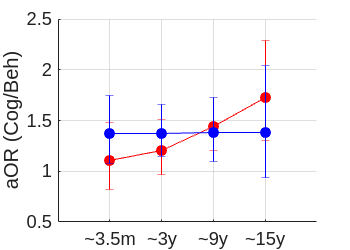

Z = -1.50: Slope = 0.3182, SE = 0.1232, p = 0.0098
Z = -1.00: Slope = 0.3189, SE = 0.0954, p = 0.0008
Z = 0.00: Slope = 0.3202, SE = 0.1158, p = 0.0057
Z = 1.00: Slope = 0.3215, SE = 0.1991, p = 0.1064


hold on; 
run_cfx_analysis(mdl4.cogbeh, 7, 9, z_vals, xlabels, 'b');set(gca, 'FontSize',14);set(gcf, 'position', [0, 0, 350, 250]);ylabel('aOR (Cog/Beh)')

% Post-hoc analyses of Left SM 

% Z-values and labels for age levels
z_vals = [-1.5,-1, 0, 1];
xlabels = {'~3.5m', '~3y', '~9y', '~15y'};

% L SM
clf;
run_cfx_analysis(mdl4.lmotor, 6, 8, z_vals, xlabels, 'r'); 

Z = -1.50: Slope = -0.4511, SE = 0.2531, p = 0.0747
Z = -1.00: Slope = -0.4314, SE = 0.1968, p = 0.0284
Z = 0.00: Slope = -0.3918, SE = 0.1694, p = 0.0207
Z = 1.00: Slope = -0.3523, SE = 0.2699, p = 0.1918


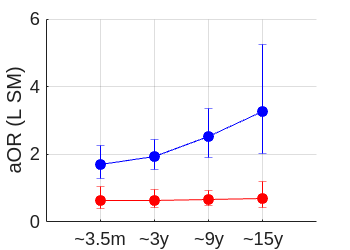

Z = -1.50: Slope = 0.5365, SE = 0.1403, p = 0.0001
Z = -1.00: Slope = 0.6658, SE = 0.1132, p = 0.0000
Z = 0.00: Slope = 0.9242, SE = 0.1456, p = 0.0000
Z = 1.00: Slope = 1.1827, SE = 0.2432, p = 0.0000


hold on; 
run_cfx_analysis(mdl4.lmotor, 7, 9, z_vals, xlabels, 'b');set(gca, 'FontSize',14);set(gcf, 'position', [0, 0, 350, 250]);ylabel('aOR (L SM)')

% Post-hoc analyses of Right SM 

% Z-values and labels for age levels
z_vals = [-1.5,-1, 0, 1];
xlabels = {'~3.5m', '~3y', '~9y', '~15y'};

% R SM
clf;
run_cfx_analysis(mdl4.rmotor, 6, 8, z_vals, xlabels, 'r'); 

Z = -1.50: Slope = 0.6391, SE = 0.1586, p = 0.0001
Z = -1.00: Slope = 0.7068, SE = 0.1249, p = 0.0000
Z = 0.00: Slope = 0.8422, SE = 0.1069, p = 0.0000
Z = 1.00: Slope = 0.9776, SE = 0.1646, p = 0.0000


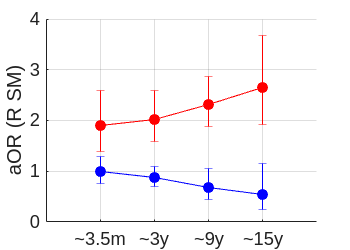

Z = -1.50: Slope = -0.0094, SE = 0.1381, p = 0.9458
Z = -1.00: Slope = -0.1317, SE = 0.1141, p = 0.2481
Z = 0.00: Slope = -0.3764, SE = 0.2218, p = 0.0898
Z = 1.00: Slope = -0.6210, SE = 0.3871, p = 0.1087


hold on; 
run_cfx_analysis(mdl4.rmotor, 7, 9, z_vals, xlabels, 'b');set(gca, 'FontSize',14);set(gcf, 'position', [0, 0, 350, 250]);ylabel('aOR (R SM)');

% Show complete model for all outcomes
mdl4.lmotor

ans = Multinomial regression with ordinal responses

                           Value        SE        tStat        pValue  
                         _________    _______    ________    __________

    (Intercept_0)          -3.0829    0.22234     -13.866     1.018e-43
    (Intercept_1)          -1.8049    0.14305     -12.618     1.688e-36
    (Intercept_2)         -0.85127    0.11435     -7.4442    9.7514e-14
    stroke_age           -0.082928    0.11306    -0.73351       0.46325
    yrs2test               0.16313    0.10062      1.6212       0.10498
    lh_vol                -0.39183    0.16943     -2.3127      0.020742
    rh_vol                 0.92424    0.14564      6.3459    2.2115e-10
    stroke_age:lh_vol     

mdl4.rmotor

ans = Multinomial regression with ordinal responses

                          Value         SE        tStat       pValue  
                         ________    ________    _______    __________

    (Intercept_0)          -3.102     0.22228    -13.955      2.92e-44
    (Intercept_1)         -1.6736     0.14114    -11.858      1.96e-32
    (Intercept_2)         -0.7663     0.11709    -6.5445    5.9707e-11
    stroke_age           -0.26032     0.11279     -2.308      0.021001
    yrs2test             0.015407     0.10078    0.15287        0.8785
    lh_vol                0.84222     0.10687     7.8812    3.2431e-15
    rh_vol               -0.37638     0.22184    -1.6966      0.089765
    stroke_age:lh_vol     0.13541  

mdl4.explang

ans = Multinomial regression with ordinal responses

                          Value         SE        tStat       pValue  
                         ________    ________    _______    __________

    (Intercept_0)         -3.0944     0.21895    -14.133    2.3808e-45
    (Intercept_1)         -1.9961      0.1494     -13.36    1.0333e-40
    (Intercept_2)         -1.1865     0.11948    -9.9301    3.0808e-23
    stroke_age           -0.29467     0.11895    -2.4772       0.01324
    yrs2test              0.15703     0.10635     1.4765       0.13981
    lh_vol                0.68403     0.10166     6.7285    1.7147e-11
    rh_vol                0.21436     0.14763      1.452       0.14651
    stroke_age:lh_vol     0.26178  

mdl4.reclang

ans = Multinomial regression with ordinal responses

                          Value        SE        tStat       pValue  
                         ________    _______    _______    __________

    (Intercept_0)         -3.4709    0.25352    -13.691    1.1495e-42
    (Intercept_1)         -2.5285    0.18188    -13.902    6.1608e-44
    (Intercept_2)         -1.7814    0.14563    -12.232    2.0947e-34
    stroke_age            -0.5403    0.14507    -3.7244    0.00019577
    yrs2test             0.053772    0.12339    0.43579       0.66299
    lh_vol                0.55107    0.10158     5.4252    5.7885e-08
    rh_vol                0.27176    0.14824     1.8333      0.066765
    stroke_age:lh_vol     0.16281     0.1016

mdl4.cogbeh

ans = Multinomial regression with ordinal responses

                           Value         SE        tStat        pValue  
                         _________    ________    ________    __________

    (Intercept_0)          -2.9783     0.21033      -14.16    1.6233e-45
    (Intercept_1)           -1.313     0.11729     -11.194    4.3386e-29
    (Intercept_2)         -0.67651     0.10256     -6.5964     4.212e-11
    stroke_age             -0.1462     0.10153       -1.44       0.14987
    yrs2test               0.19572    0.095057       2.059      0.039492
    lh_vol                 0.36756    0.091473      4.0182    5.8638e-05
    rh_vol                 0.32017     0.11576      2.7659     0.0056766
    stroke_age:lh_vol

% Show base model for all outcomes
mdl1.lmotor

ans = Multinomial regression with ordinal responses

                       Value        SE        tStat        pValue  
                     _________    _______    ________    __________

    (Intercept_0)      -3.1138    0.22159     -14.052    7.5031e-45
    (Intercept_1)      -1.8443    0.14168     -13.018    9.7231e-39
    (Intercept_2)     -0.90131    0.11217     -8.0354    9.3254e-16
    stroke_age       -0.087654    0.10727    -0.81716       0.41384
    yrs2test           0.15495    0.10053      1.5413       0.12325
    lh_vol            -0.47971    0.17501      -2.741     0.0061252
    rh_vol             0.75281    0.11241      6.6968      2.13e-11


469 observations, 1400 error degrees of freedom
Dispersion: 1
Chi^2-statistic

mdl1.rmotor

ans = Multinomial regression with ordinal responses

                      Value        SE        tStat       pValue  
                     ________    _______    _______    __________

    (Intercept_0)     -3.0387     0.2161    -14.061    6.5608e-45
    (Intercept_1)     -1.6151    0.13041    -12.384     3.178e-35
    (Intercept_2)    -0.71201    0.10441    -6.8196    9.1319e-12
    stroke_age        -0.1949    0.10363    -1.8807      0.060013
    yrs2test         0.019075    0.10056    0.18968       0.84956
    lh_vol            0.83879    0.10322     8.1263    4.4259e-16
    rh_vol           -0.14716    0.10895    -1.3507       0.17679


469 observations, 1400 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant mode

mdl1.explang

ans = Multinomial regression with ordinal responses

                      Value         SE        tStat       pValue  
                     ________    ________    _______    __________

    (Intercept_0)     -3.0275     0.21229    -14.261    3.8173e-46
    (Intercept_1)     -1.9567     0.14527     -13.47    2.3518e-41
    (Intercept_2)     -1.1623     0.11563    -10.052    8.9851e-24
    stroke_age       -0.22817     0.11505    -1.9831      0.047354
    yrs2test          0.17755     0.10583     1.6777      0.093414
    lh_vol            0.65563    0.096734     6.7777     1.221e-11
    rh_vol             0.3346     0.09652     3.4667     0.0005269


469 observations, 1400 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. cons

mdl1.reclang

ans = Multinomial regression with ordinal responses

                      Value         SE        tStat       pValue  
                     ________    ________    _______    __________

    (Intercept_0)     -3.4531     0.25181    -13.713    8.4873e-43
    (Intercept_1)     -2.5115     0.17894    -14.035     9.493e-45
    (Intercept_2)     -1.7664     0.14161    -12.473    1.0435e-35
    stroke_age       -0.49164     0.13912     -3.534    0.00040936
    yrs2test         0.069911     0.12278    0.56938        0.5691
    lh_vol            0.51378    0.096855     5.3046     1.129e-07
    rh_vol            0.24107    0.098531     2.4466      0.014419


469 observations, 1400 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. cons

mdl1.cogbeh

ans = Multinomial regression with ordinal responses

                      Value         SE        tStat       pValue  
                     ________    ________    _______    __________

    (Intercept_0)     -2.9804     0.20916     -14.25    4.5149e-46
    (Intercept_1)     -1.3248     0.11599    -11.421    3.2715e-30
    (Intercept_2)    -0.69216     0.10099    -6.8535    7.2071e-12
    stroke_age       -0.14638     0.10104    -1.4488       0.14739
    yrs2test          0.20528    0.094796     2.1655       0.03035
    lh_vol            0.32754    0.088339     3.7077    0.00020913
    rh_vol            0.30086    0.090111     3.3387    0.00084159


469 observations, 1400 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. cons